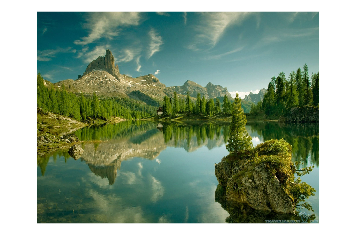

im=imread("C:\Users\91950\Downloads\image2.jpeg");
imshow(im)

[net,classNames]=imagePretrainedNetwork("googlenet");

net.Layers

ans =   143×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   2-D Convolution               64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               2-D Convolution               64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      2-D Convolution           

inputSize=net.Layers(1).InputSize

inputSize =    224   224     3


im=imresize(im,inputSize(1:2));
x=single(im);
score=predict(net,x);

Label2=scores2label(score,classNames);
Label2

Label2 = categorical
     valley 
